# Spike Triggered Averaging (STA) 

Here we want to explore how neurons respond to stimuli. We are going to construct a linear-nonlinear model to simulate the firing rate responses of a neuron in reaction to a time-varying noise stimulus. This model will include three main components: a linear filter, a thresholding nonlinearity, and a mechanism for spike generation. Our objective is to create each element of this model and produce a synthetic spike train. Subsequently, by utilizing the technique of spike-triggered averaging (STA), we will analyze this synthetic spike train to reconstruct and understand the receptive field of the neuron.

STA is a common method to determine the relationship between stimuli and neural response. It is frequently used in receptive field mapping. 

First of all let's simulate a neuron with a center-surround receptive field (RF). This is a typical structure in retina and thalamus (LGN). We can do that by subtracting two 2D Gaussian function: a narrow one for the center and a broader one for the surround. 

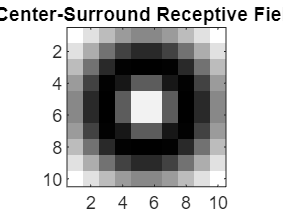

% Define the size of the receptive field
rfSize = 10; % Size of the receptive field
[x, y] = meshgrid(linspace(-5, 5, rfSize), linspace(-5, 5, rfSize));

% Define parameters for the Gaussians
centerSigma = 1; 
surroundSigma = 3;


% Create the center and surround Gaussians
centerGaussian = exp(-(x.^2 + y.^2) / (5 * centerSigma^2));
surroundGaussian = exp(-(x.^2 + y.^2) / (2 * surroundSigma^2));

% Create the receptive field by subtracting the surround from the center
receptiveField = centerGaussian - surroundGaussian;

% Plot the receptive field
figure;
imagesc(receptiveField);
colormap('gray');
axis image;
title('Center-Surround Receptive Field');

In the next step we generate a random noise stimulus to evoke some spikes from our neurons. Our neuron integrates luminance our space and time. Each pixel of the stimulus changes every milisecond so what we need to do is to multiply our Gaussian filter by stimulus at each time point and integrate our space and time. The stimulus is presented for 1000 ms i.e each pixel changes 1000 times independent of other pixels. Lets assum we know that RF is located at upper right quadrant of screen.  

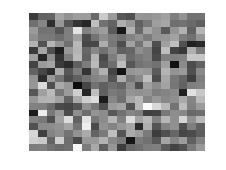

% Parameters
refreshRate = 1000; 
duration = 1; % Duration of the stimulus in seconds
screenSize = [10, 10];

% Total number of frames
numFrames = duration * refreshRate;

% Generate Gaussian white noise
noiseStimulus = randn([screenSize, numFrames]);

% Demonstrate the stimulus for the first 200 ms
for frame = 1:200
    imagesc(noiseStimulus(:, :, frame), [-3, 3]); % Displaying each frame
    colormap gray;
    axis off;
    pause(1 / refreshRate); % Pause to simulate
end

Now we need to pass the stimulus through our filter (RF structure). The RF should integraste both over space and time. Let's assume that integration window is 25 ms. 

windSize = 10;
integWindow = [1:1:numFrames-windSize+1; windSize:1:numFrames]';
for win_i = 1:size(integWindow,1)
    integration_i = repmat(receptiveField,[1,1,windSize]) .* noiseStimulus(1:10,11:20,integWindow(win_i,1):integWindow(win_i,2));
    integrations(1,win_i) = sum(integration_i,'all');
end



Our neuron fires an action potential whenever the integration passes 2 standard deviation from the mean of all integrations over the couse of trial.

aveIntegration = mean(integrations);
stdIntegration = std(integrations);
spikeTimes = find(integrations > (aveIntegration + stdIntegration));


Now we have spkies of our neurons in response to our stimulus.

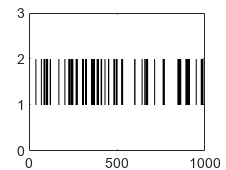

plot([spikeTimes; spikeTimes],[1,2],'k')
ylim([0 3])